## Análisis del transistor BFP450

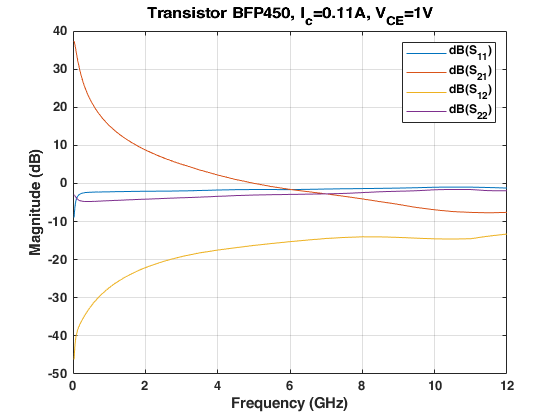

bfp450_polarizado = sparameters('BFP450_w_noise_VCE_1.0V_IC_0.11A.s2p');
rfplot(bfp450_polarizado)
title('Transistor BFP450, I_c=0.11A, V_{CE}=1V')

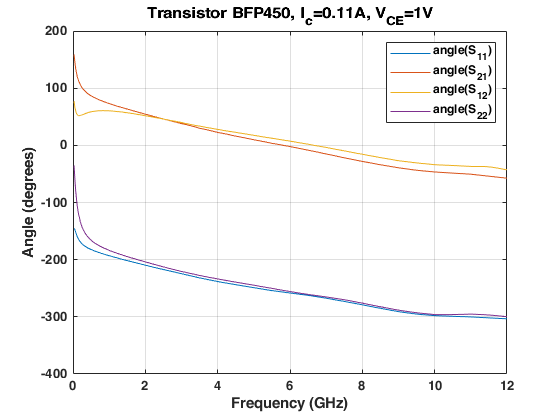

rfplot(bfp450_polarizado,'angle')
title('Transistor BFP450, I_c=0.11A, V_{CE}=1V')

## Sistema diseñado

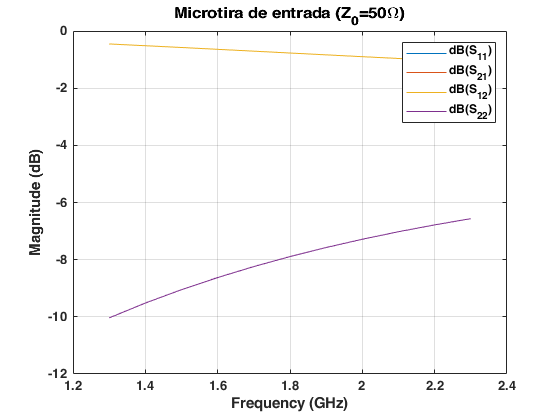

microstrip_in1 = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 10e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
microstrip_in2 = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 10e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
lamb4_in = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 7.37e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 22.5e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
cap_in = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 19.4e-3, ...
    "StubMode", "Shunt",...
    "Termination", "Open"...
    );
bfp = sparameters('BFP450_w_noise_VCE_1.0V_IC_0.11A.s2p');
lamb4_out = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 5.99e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 22.79e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
cap_out = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 4.99e-3, ...
    "StubMode", "Shunt",...
    "Termination", "Open"...
    );
microstrip_out1 = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 10e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
microstrip_out2 = txlineMicrostrip( ...
    "EpsilonR", 4.15, ...
    "Width", 3.19e-3, ...
    "Thickness", 35e-6, ...
    "LineLength", 10e-3, ...
    "StubMode", "NotAStub",...
    "Termination", "NotApplicable"...
    );
freq = (13:23)*100e6;
s1 = sparameters(microstrip_in1,freq,50);
s2 = sparameters(microstrip_in2,freq,50);
s3 = sparameters(lamb4_in,freq,50);
s4 = sparameters(cap_in,freq,50);
s5 = sparameters(lamb4_out,freq,50);
s6 = sparameters(cap_out,freq,50);
s7 = sparameters(microstrip_out1,freq,50);
s8 = sparameters(microstrip_out2,freq,50);
rfplot(s1)
title('Microtira de entrada (Z_0=50\Omega)')

rfplot(s2)
title('Microtira de entrada (Z_0=50\Omega)')

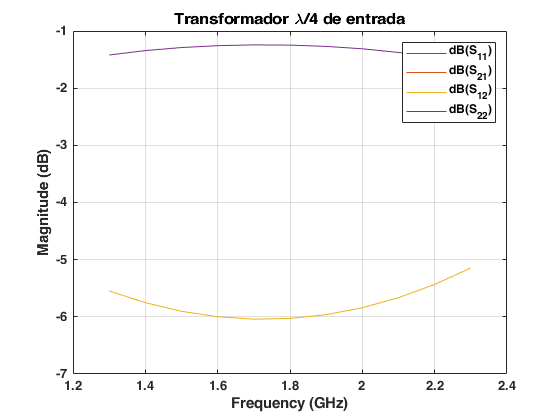

rfplot(s3)
title('Transformador \lambda/4 de entrada')

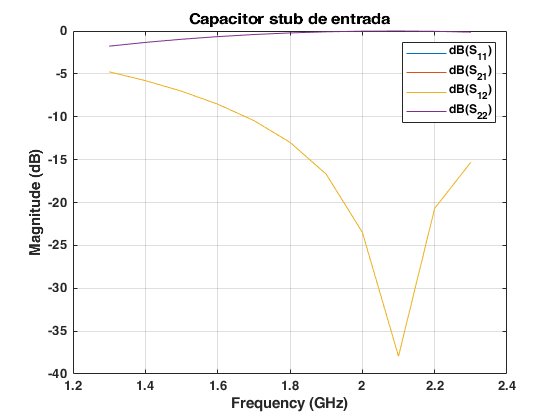

rfplot(s4)
title('Capacitor stub de entrada')

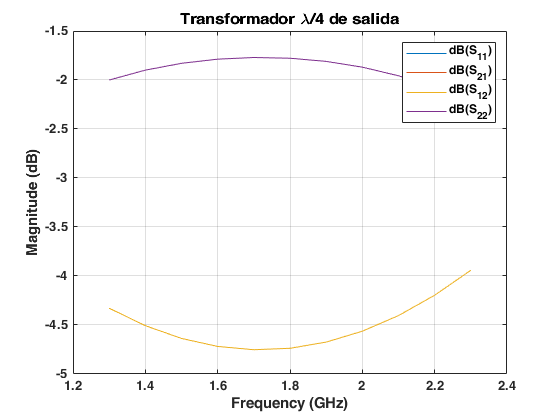

rfplot(s5)
title('Transformador \lambda/4 de salida')

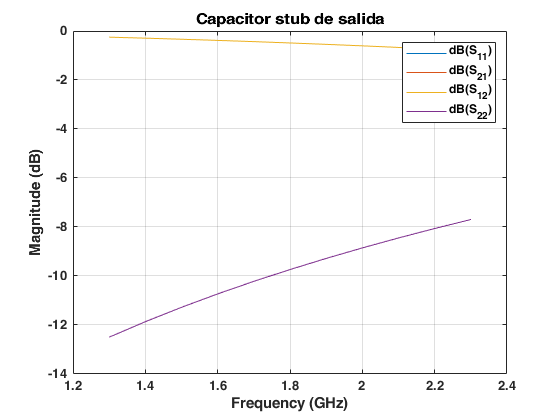

rfplot(s6)
title('Capacitor stub de salida')

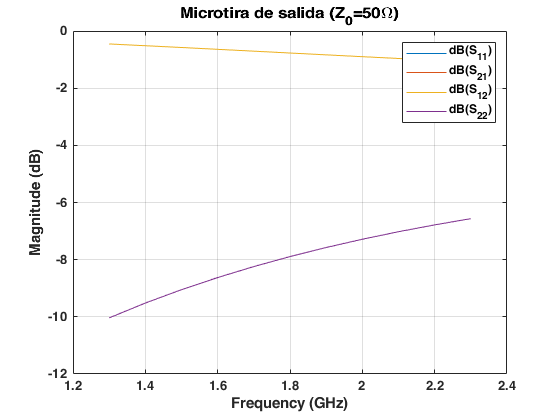

rfplot(s7)
title('Microtira de salida (Z_0=50\Omega)')

rfplot(s8)
title('Microtira de salida (Z_0=50\Omega)')